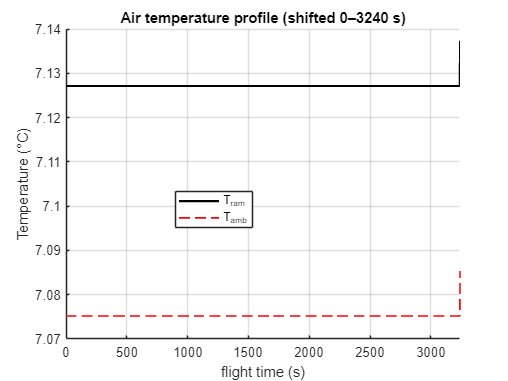

%% Plot parameters(t) on shifted window: original [421, 3660] → new [0, 3240]
% Run the whole script so MATLAB registers the local functions below.

t0 = linspace(0, 3240, 3241);                 % new time base [s]
[Temp, Speed, rho] = parameters_0to3240(t0);  % Temp [°C], Speed [m/s], rho [kg/m^3]

% Recreate altitude [ft] and ambient temperature [°C] for plotting,
% evaluated at original time t = t0 + 421 (same formulas as your code)
T_off = 60;  t_cruise = 420;  t_landing = 3660;  t_final = 4440;
r_slope  = (4000-50)/(t_cruise-T_off);
r_slope2 = (0-4000)/(t_final - t_landing);
step_ft  = 50;

ts = t0 + 421;                                 % back to original timeline
r1 = zeros(size(ts)); r1(ts >= T_off)     = r_slope  * (ts(ts >= T_off)     - T_off);
r2 = zeros(size(ts)); r2(ts >= t_cruise)  = -r_slope * (ts(ts >= t_cruise)  - t_cruise);
r3 = zeros(size(ts)); r3(ts >= t_landing) = r_slope2 * (ts(ts >= t_landing) - t_landing);

h_ft = step_ft + r1 + r2 + r3;  h_ft(h_ft < 0) = 0;  % altitude [ft]
h_m  = 0.3048 * h_ft;                                % altitude [m]

Gamma = 1.4; R = 287.053;
T_amb = -6.5e-3 * h_m + 15;                          % ambient temperature [°C]
a_plot = sqrt(Gamma * R * (T_amb + 273.15));         % speed of sound [m/s]
Mach   = Speed ./ a_plot;                            % consistent Mach for plotting

% ---- (1) Air temperature profile: T_ram vs T_amb ----
figure('Name','Air temperature profile'); hold on; grid on
plot(t0, Temp, 'k', 'LineWidth', 1.6)                % T_ram from function
plot(t0, T_amb, 'r--', 'LineWidth', 1.2)             % T_amb recomputed for plot
xlabel('flight time (s)'); ylabel('Temperature (°C)')
title('Air temperature profile (shifted 0–3240 s)')
legend('T_{ram}','T_{amb}','Location','best'); xlim([0 3240])

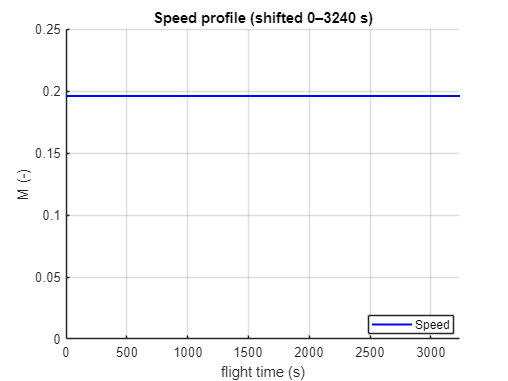


% ---- (2) Speed profile in Mach ----
figure('Name','Speed profile'); hold on; grid on
plot(t0, Mach, 'b', 'LineWidth', 1.6)
xlabel('flight time (s)'); ylabel('M (-)')
title('Speed profile (shifted 0–3240 s)')
xlim([0 3240]); ylim([0 0.25])   % keeps the horizontal cruise line visible
legend('Speed','Location','best')

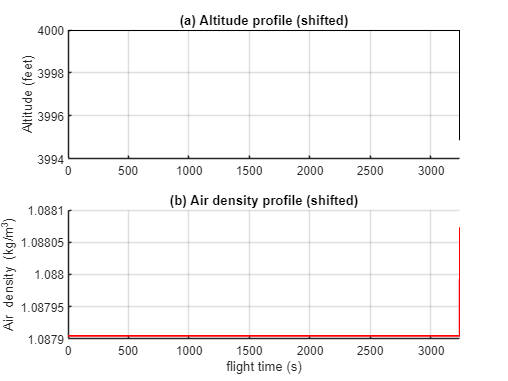


% ---- (3) Altitude (ft) and Air density (kg/m^3) ----
figure('Name','Altitude & Air density')
subplot(2,1,1); hold on; grid on
plot(t0, h_ft, 'k', 'LineWidth', 1.4)
ylabel('Altitude (feet)'); title('(a) Altitude profile (shifted)'); xlim([0 3240])
subplot(2,1,2); hold on; grid on
plot(t0, rho, 'r', 'LineWidth', 1.6)
xlabel('flight time (s)'); ylabel('Air density (kg/m^3)')
title('(b) Air density profile (shifted)'); xlim([0 3240])


% (Optional) quick sanity printouts
fprintf('Speed range: %.2f–%.2f m/s | Mach range: %.3f–%.3f\n', min(Speed), max(Speed), min(Mach), max(Mach));

Speed range: 65.69–65.72 m/s | Mach range: 0.196–0.196


fprintf('rho range:   %.3f–%.3f kg/m^3\n', min(rho), max(rho));

rho range:   1.088–1.088 kg/m^3




%% Local wrapper that shifts the timeline but keeps your code unchanged

function [Temp, Speed, rho] = parameters_0to3240(tprime)
% Map new domain t' ∈ [0, 3240] to original t = t' + 421 and call your original code.
    if any(tprime(:) < 0 | tprime(:) > 3240)
        error('t'' must be within 0 to 3240 seconds.');
    end
    [Temp, Speed, rho] = parameters_original(tprime + 421);
end

%% Your original function (unchanged)
function [Temp, Speed, rho] = parameters_original(t)
    %% Calculates aircraft altitude in ft and m
    T_off = 60;
    t_cruise = 420;
    t_landing = 3660;
    t_final = 4440;

    r_slope = (4000-50)/(t_cruise-T_off);
    r_slope2 =(0-4000)/(t_final-t_landing);
    step = 50;

    r_ramp1 = zeros(size(t));
    r_ramp1(t >= T_off) = r_slope * (t(t >= T_off) - T_off);

    r_ramp2 = zeros(size(t));
    r_ramp2(t >= t_cruise) = -r_slope * (t(t >= t_cruise) - t_cruise);

    r_ramp3 = zeros(size(t));
    r_ramp3(t >= t_landing) = r_slope2 * (t(t >= t_landing) - t_landing);

    h = step + r_ramp1 + r_ramp2 + r_ramp3;
    h(h < 0) = 0;
    h = 0.3048 * h;   % meters

    %% Ambient temperature and speed of sound
    Gamma = 1.4; R = 287.053;
    T_amp = -6.5e-3 * h + 15;                 % °C
    a = sqrt(Gamma * R * (T_amp + 273.15));   % m/s

    %% Aircraft speed → knots → m/s → Mach
    s_slope_1 = 77/60;
    s_slope_2 = (125 - 77) / (t_cruise - T_off);
    s_slope_3 = (78 - 125) / (t_final - t_landing);

    S_ramp  = zeros(size(t));
    S_ramp(t <= T_off) = s_slope_1 * t(t <= T_off);

    S_ramp1 = zeros(size(t));
    S_ramp1(t > T_off & t < t_cruise) = s_slope_2 * (t(t > T_off & t < t_cruise) - T_off) + 77;

    S_ramp2 = zeros(size(t));
    S_ramp2(t >= t_cruise & t <= t_landing) = 125;

    S_ramp3 = zeros(size(t));
    S_ramp3(t > t_landing & t <= t_final) = s_slope_3 * (t(t > t_landing & t <= t_final) - t_landing) + 125;

    S_ramp4 = zeros(size(t));
    S_ramp4(t > t_final) = s_slope_3 * (t(t > t_final) - t_final) + 78;

    knot = S_ramp + S_ramp1 + S_ramp2 + S_ramp3 + S_ramp4;  % knots
    knot = 0.5144 * knot;        % m/s
    Mach = knot ./ a;

    Speed = Mach * 343;          % m/s (kept as in your code)
    %% Ram temperature
    Temp = T_amp .* (1 + Mach.^2 * ((Gamma - 1)/2));

    %% Pressure altitude and density
    P0 = 101325;                                     % Pa
    P  = P0 * (1 - 2.25577e-5 * h).^5.25588;         % Pa
    rho = P ./ (R * (T_amp + 273.15));               % kg/m^3
end